# Documentation and visualization

## Generate stf (steering information)-> update needed

The  - `generateStf.m` function gets three objects input arguments (no values are assigned inside the function):

- Information about the ct voxels `ct`

- The classification of these voxels into different organs and tissue` cst`

- Informaion about the radiation treatment plan` pln`

It the output is the `stf`  struct with the following fields: 

- target volume:           voxel coordnates of target

- template:                   3xN array with 2D template point unit positions

- radiation mode:         string `'brachy'`

- needle info:               needle information: seed number and distance

- orientation:                unit vectors of final template position and offset

- seed info:                  Source information relevant for dose calculation

- seed positions:           3D array with dimentions (needle number, seed number, coord in mm)

### Initial visualization of seed points

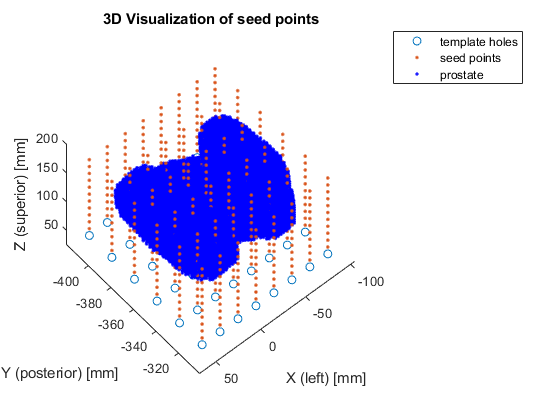

%rotated template
clf
template3D = stf.template.template3D;
Template = plot3(template3D(1,:),template3D(2,:),template3D(3,:),'o','DisplayName', 'template holes');
legend(Template(:))
hold on
%Z direction
seedsX = reshape(stf.seedPosX,[],1);
seedsY = reshape(stf.seedPosY,[],1);
seedsZ = reshape(stf.seedPosZ,[],1);
Zvec = zeros(3,2);
for i = 1:3
    Zvec(i,:) = [pln.propStf.orientation.offset(i),pln.propStf.orientation.offset(i)+pln.propStf.needle.seedDistance*pln.propStf.needle.seedsNo*pln.propStf.orientation.Zdir(i)];
end
%TempNormal = plot3(Zvec(1,:),Zvec(2,:),Zvec(3,:),'DisplayName', 'template normal');
%3D seed positions
SeedPoints = plot3(seedsX,seedsY,seedsZ,'.','DisplayName', 'seed points');
title( '3D Visualization of seed points')
xlabel('X (left) [mm]')
ylabel('Y (posterior) [mm]')
zlabel('Z (superior) [mm]')
% 3d VOI points
TargX = stf.targetVolume.Xvox;
TargY = stf.targetVolume.Yvox;
TargZ = stf.targetVolume.Zvox;
Prostate = plot3(TargX,TargY,TargZ,'.', 'Color','b','DisplayName', 'prostate');


%outer points of ct grid
% ctX = [ct.x(1),ct.x(end),ct.x(end),ct.x(1),ct.x(1),ct.x(1),ct.x(end),ct.x(end),ct.x(1),ct.x(1)];
% ctY = [ct.y(1),ct.y(1),ct.y(end),ct.y(end),ct.y(1),ct.y(1),ct.y(1),ct.y(end),ct.y(end),ct.y(1)];
% ctZ = [ct.z(1),ct.z(1),ct.z(1),ct.z(1),ct.z(1),ct.z(end),ct.z(end),ct.z(end),ct.z(end),ct.z(end)];
% 
% plot3(ctX,ctY,ctZ)

% % dijDoseGrid
% [DGX,DGY,DGZ] = meshgrid(dij.doseGrid.x, dij.doseGrid.y, dij.doseGrid.z);
% DoseGridX = reshape(DGX,[],1);
% DoseGridY = reshape(DGY,[],1);
% DoseGridZ = reshape(DGZ,[],1);
% plot3(DoseGridX,DoseGridY,DoseGridZ,'.')
hold off

clear DoseGridX DoseGridY DoseGridZ DGX DGY DGZ seedsX seedsY seedsZ TargX TargY TargZ template3D

## Generate dij (dose matrix calculation)

The `-calcDose.m` - Function gets the following inputs:

- ct

- stf

- pln

- cst

The output is the `dij` struct with the following fields

- dose grid:                             resolution, dimentions, grid coordinates

- ct grid:                                  resolution, dimentions, grid coordinates

- numOfNeedles                    

- numOfSeedsPerNeedle

- pysicalDoseMatrix                physicalDose

### Layerwise visualization of dose 

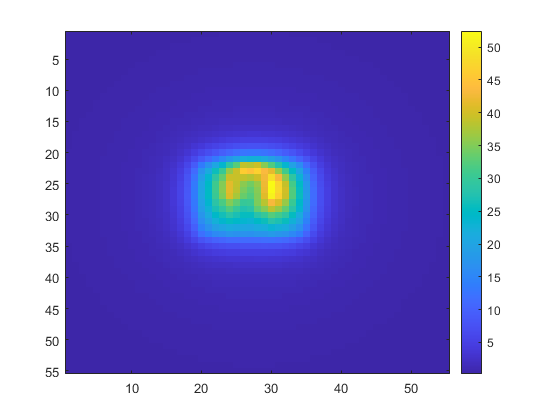

% Z-slice
slice = 7;
D = dij.physicalDose{1,1};
weight = resultGUI.wUnsequenced;
%weight(502) = 1;
Dose = D*weight;
P = reshape(Dose,[length(dij.doseGrid.y),length(dij.doseGrid.x) ,length(dij.doseGrid.z)]);

image(P(:,:,slice),'CDataMapping','scaled')
colorbar